# Fitting a mixed distance-domain model

#### Author: Luis Fabregas

This short tutorial will cover some basic manipulation of parametric models for fitting distance distributions.

## Simulate the data

Let's start by creating a simple dipolar evolution function (i.e. no background and full modulation depth) corresponding to a simple 4-pulse DEER signal.

clear,clc,clf

%Fix random number generator
rng(4)

%Axis definition
t = linspace(-0.5,4,350);
r = linspace(2,6,200);

%Distribution parameters
rmean = 4.5;
width = 0.3;
chain = 4.3;
pers = 10;
amp = 0.35;

%Generate distribution
P = rd_onegaussian(r,[rmean width]);
P = amp*P + (1 - amp)*rd_wormchain(r,[chain pers]);
%Normalize distribution
P = P/sum(P)/mean(diff(r));
%Generate dipolar evolution function
D = dipolarsignal(t,r,P,'noiselevel',0.02);

## Generating a mixed parametric model

Let's say our intuiton (which, since we know the ground truth, is exact) on the sample indicates that our distribution is a llinear combination of a Gaussian distirbution and a worm-like chain model. While DeerAnalysis provides built-in parametric models for both models, we require a combination of both. 

For such cases we can use the `mixmodels` function to create a custom mixed parametric model. It's syntax is rather simple, we just have to pass the desired parametric models as function handles (this means using the decorator @). 

%Mix the models into new one
gausswlc = mixmodels({@rd_onegaussian,@rd_wormchain});

Our new model `gausswlc` will now describe our sought linear combination of both parametric models. We can check the state of the model by retrieving its information

%Get information on the mixed model
info = gausswlc();
info.parameters

ans = 1×5 struct array with fields:
    name
    range
    default
    units


 We can see that the `mixmodels` function has introduced an ampitude parameters as the first parameter of the model. This parameters weights the contribution of each individual parametric model. We see also that this is followed by the parameters of the Gaussian model and finally with the parameters of the WLC model.

## Fitting the mixed model

Our model is ready, and since it was generated from built-in models we do not need to specify any parameters initial values or boundary constraints. These can, however, by re-defined if the built-in defaults are not appropiate (see other tutorials). 

Since we are dealing with a distance-domain model we require a dipolar kernel to transform our model into time-domain. Remember that our signal in this example is a dipolar evolution function, therefore we do not require anything else than a very basic dipolar kernel.

%Generate the dipolar evolution function kernel
K = dipolarkernel(t,r);

Now we can call `fitparamodel` to fit our mixed model to our signal. 

%Fit the model to the data
paramfit = fitparamodel(D,gausswlc,r,K);

From the fitted parameter set `paramfit` we can now generate our fitted distance distribution and the corresponding time-domain fit.

%Calculate the fitted model
Pfit = gausswlc(r,paramfit);
Dfit = K*Pfit;

Since we know both the ground truth for the distance distribution and the dipolar signal, let's see how our fit turned out.

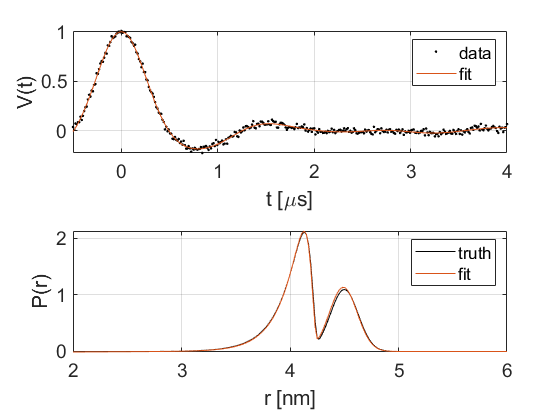

%Plot results
subplot(211)
plot(t,D,'k.',t,Dfit)
xlabel('t [\mus]')
ylabel('V(t)')
legend('data','fit')
axis tight, grid on, box on
set(gca,'FontSize',14)

subplot(212)
plot(r,P,'k',r,Pfit)
xlabel('r [nm]')
ylabel('P(r)')
legend('truth','fit')
axis tight, grid on, box on
set(gca,'FontSize',14)

While for this noise realization, the fit is impecable, if the `rng()` at the beginning of the tutorial is removed, one can see that not all noise realizations lead to a good fit. For this reason, sensitivity analysis is of uttermost importance even when dealing with such simple examples and/or models. See the other tutorials for details on sensitivity analysis of parametric models.